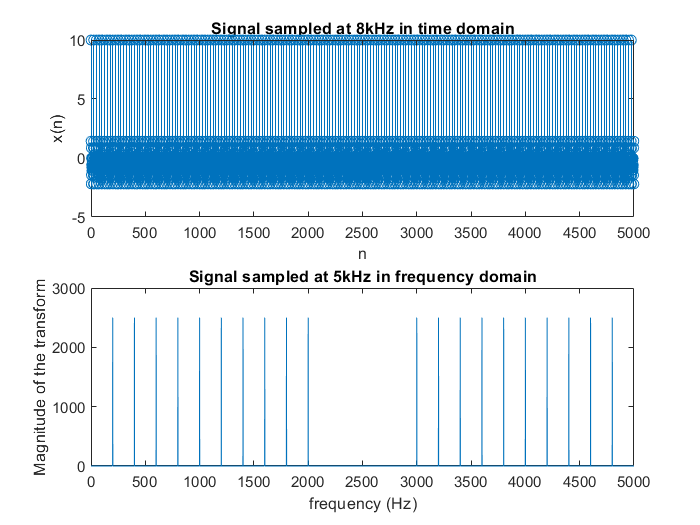

clear all;
close all;
clc;

f = 200; % Signal fundamental frequency of 200Hz.
fs= 5000; % Sampling frequency of 5kHz.
N = 5000; % Since duration of the signal is 1s, and fs=5kHz, we need 5000 samples.
n = 0:N-1;
T= 1/fs; % Sample period.
x = zeros(10,5000); % Matrix for the whole signal
for i = 1:10
    x(i,:) = cos(2*pi*i*f*n*T);
end

signal_supersition = sum(x, 1);
subplot(2,1,1);
stem(n, signal_supersition);
% stem(n*T, signal_supersition);
xlabel('n');
ylabel('x(n)');
title(['Signal sampled at 8kHz in time domain']);
% soundsc(signal_supersition);

fft_for_signal = fft(signal_supersition);
f = 0:4999;
subplot(2,1,2);
plot(f, abs(fft_for_signal));
xlabel('frequency (Hz)');
ylabel('Magnitude of the transform');
title('Signal sampled at 5kHz in frequency domain');
hold off;

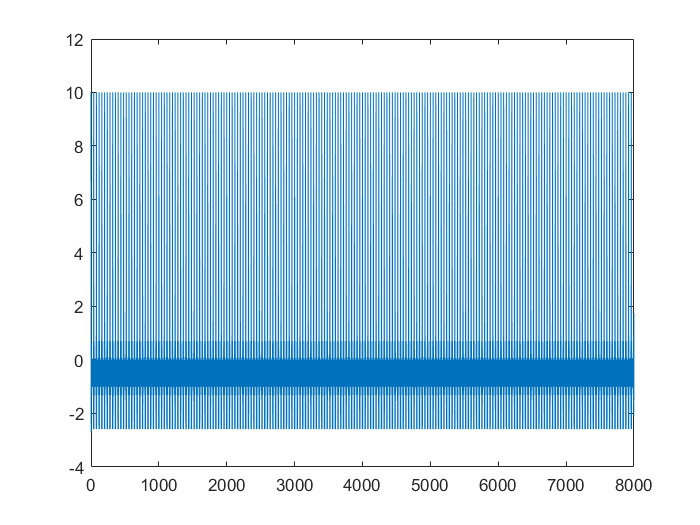


% Test for resample to 8kHz.
resampled_signal = resample(signal_supersition, 8, 5);
figure
k = 0:7999;
plot(k, resampled_signal)

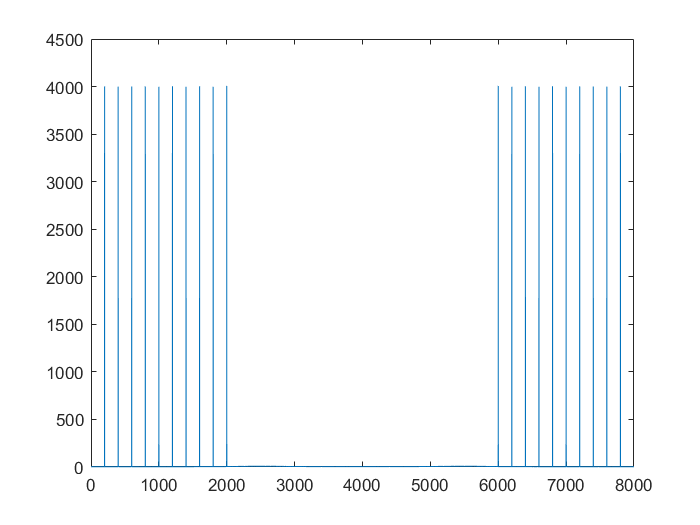

fft_for_resampled_signal = fft(resampled_signal);
plot(k, abs(fft_for_resampled_signal))

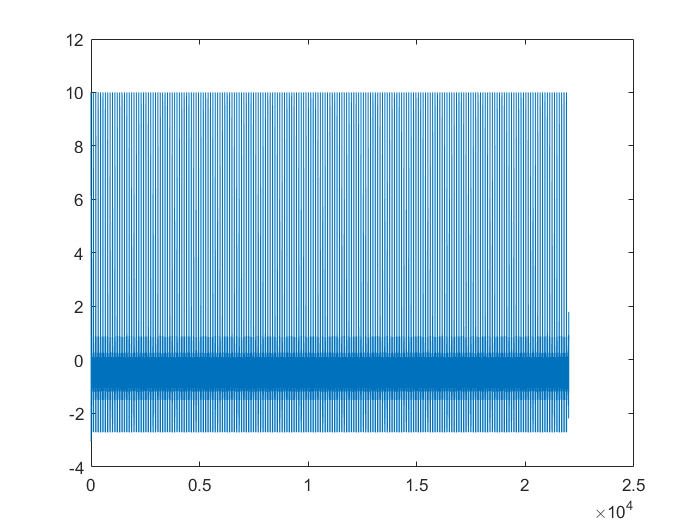


% Test for resample to 22kHz.
resampled_signal = resample(signal_supersition, 22, 5);
figure
k = 0:21999;
plot(k, resampled_signal)

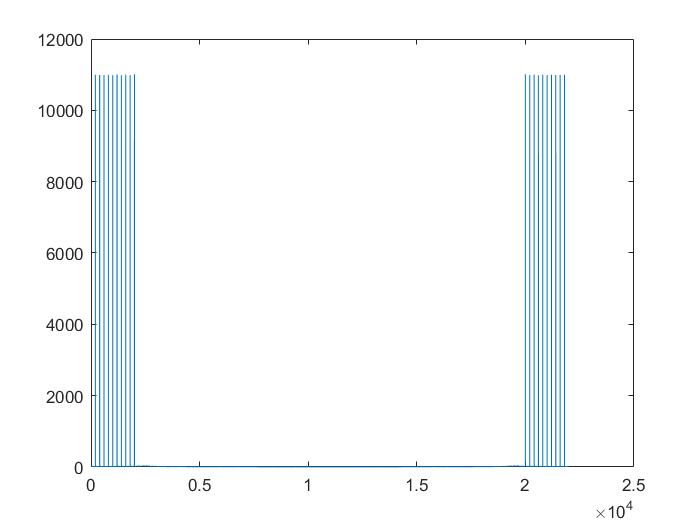

fft_for_resampled_signal = fft(resampled_signal);
plot(k, abs(fft_for_resampled_signal))

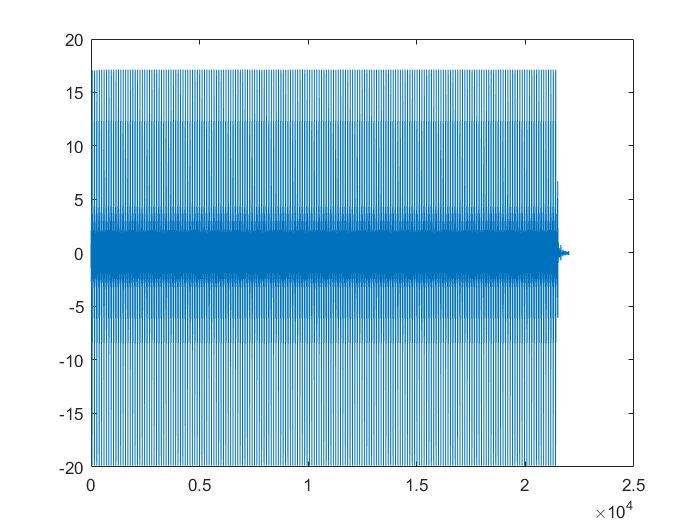


% Test for the 22kHz signal convolve with filter
filter_samples = audioread('telephoneIR.wav');
signal_after_filter = conv(resampled_signal, filter_samples, 'same');
k = 0:21999;
plot(k, signal_after_filter)

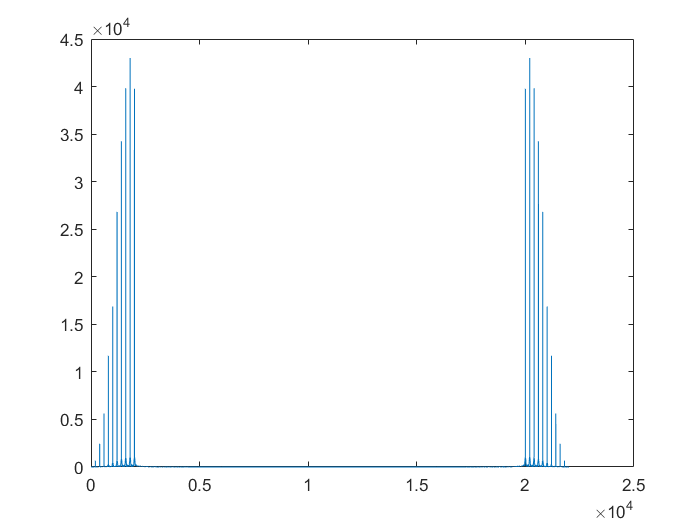

fft_for_resampled_signal = fft(signal_after_filter);
plot(k, abs(fft_for_resampled_signal))

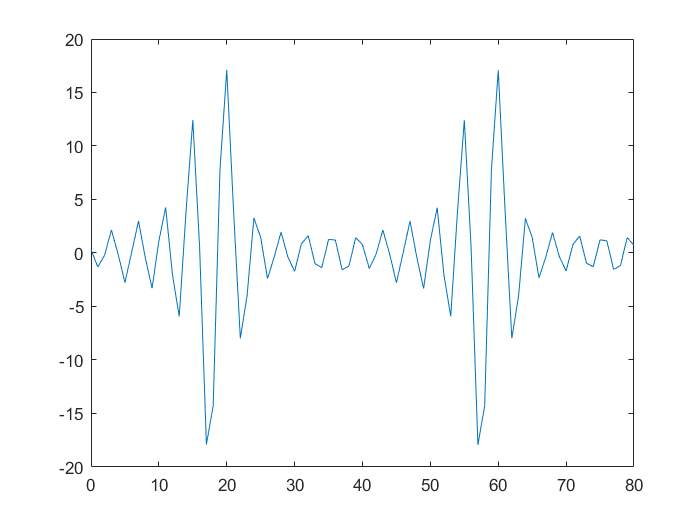


% Test resample the signal after filter.
final_8kHz_filtered_signal = resample(signal_after_filter, 8, 22);
k = 0:7999;
plot(k, final_8kHz_filtered_signal)
xlim([0 80])

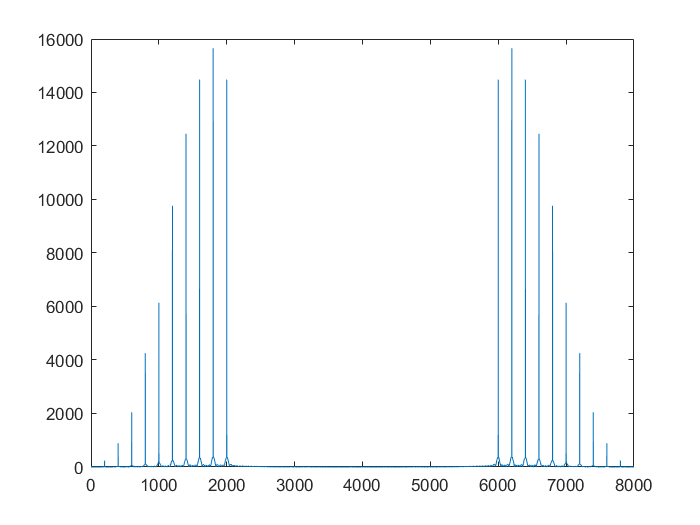

fft_for_resampled_signal = fft(final_8kHz_filtered_signal);
plot(k, abs(fft_for_resampled_signal))

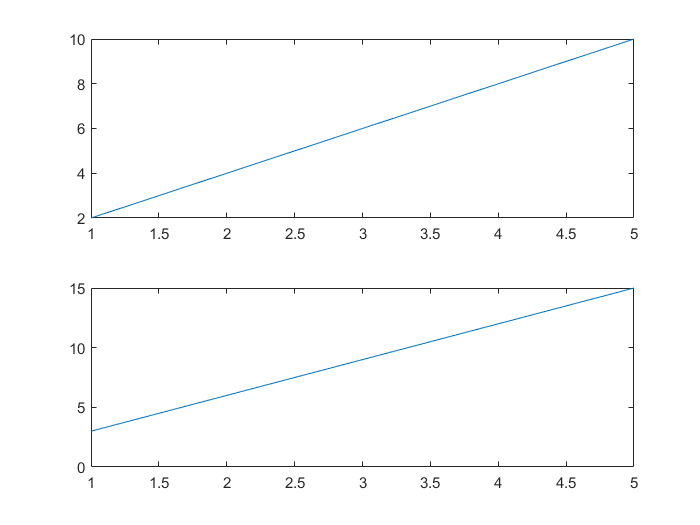

clear all;
close all;
clc;

x = 1:5;
y1 = 2*x;
y2 = 3*x;
y3 = x.^2;
y4 = x.^4;
y5 = 5*x - 1;

subplot(1,3,1);
% hold on;
subplot(2,1,1);
plot(x, y1);
subplot(2,1,2);
plot(x, y2);

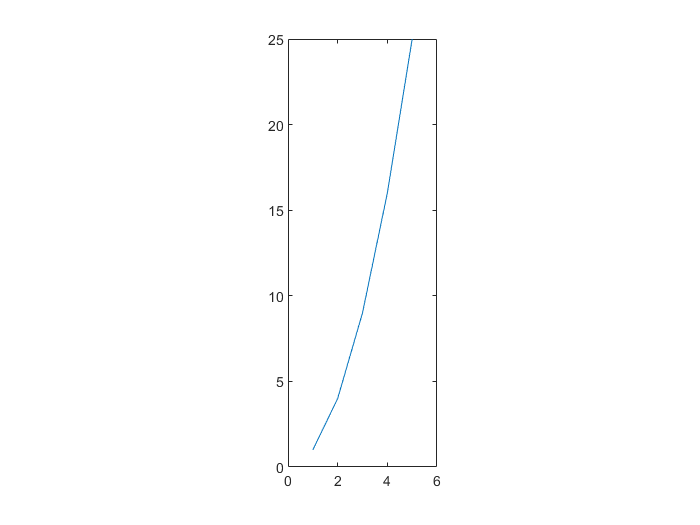

subplot(1,3,2);
plot(x, y3);